# Spike Count Analysis

Spiking actvitiy of neurons is the main focus of the [Steinmetz et al, 2019 paper](https://www.nature.com/articles/s41586-019-1787-x). With the rich dataset that they collected during their experiments many analyses are possible that can link neural activity to behavioral or experimental variables.

This notebook has a different flavor compared to the other notebooks which we worked with before. 

It resembles a research scenario where we strive to understand and explore the data, and ultimately using it to answer questions.

The exercises are more generic and there are fewer hints - this offers a fantastic opportunity to collaborate with your colleagues!

### TODO UPDATE SCIEBO LINK!!!! Download Data 

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
%download_from_sciebo('https://uni-bonn.sciebo.de/s/YT3iaH9Po0LJMxR', 'data/steinmetz_2017-12-05_Lederberg.nc')
addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

### Load in Data

spike_counts = ncread("data/steinmetz_2017-12-05_Lederberg.nc","spike_count") ;
brain_areas = ncread("data/steinmetz_2017-12-05_Lederberg.nc","brain_groups") ;
trials = ncread("data/steinmetz_2017-12-05_Lederberg.nc","trial");
cell = ncread("data/steinmetz_2017-12-05_Lederberg.nc","cell")

cell = 698×1 int32 column vector
    1
    2
    3
    4
    5
    6
    7
    8
    9
   10


time = ncread("data/steinmetz_2017-12-05_Lederberg.nc","time");
%load all relevant data into structure time, cells, trials, spieks etc...
data=struct("spike_counts", spike_counts, "brain_areas", brain_areas, "trial", trials, "cell", cell,"time",time)

data = struct with fields:
    spike_counts: [250×340×698 int8]
     brain_areas: [698×1 string]
           trial: [340×1 int32]
            cell: [698×1 int32]
            time: [250×1 double]


%save("data/2017-12-05_Lederberg.mat","-struct", "data" )

data = load("data/2017-12-05_Lederberg.mat")

data = struct with fields:
    spike_counts: [250×340×698 int8]
     brain_areas: [698×1 string]
           trial: [340×1 int32]
            cell: [698×1 int32]
            time: [250×1 double]


spike_counts = data.spike_counts;
brain_areas = data.brain_areas;
trials = data.trial;
cells = data.cell;
time = data.time;

## Slicing Matrices:  Finding Neural Spikes

Neurons in this dataset are labeled with their brain area. Let's take advantage of this additional information and compare the spiking activity for different brain areas.

**Example Exercise**

What are the dimensions of the data stored in the variable `trials`?

size(trials)

ans =    340     1


**Exercises**

What are the dimensions of the data stored in the variable **cells**?

size(cells)

ans =    698     1


What are the dimensions of the data stored in the variable **time**?

size(time)

ans =    250     1


What are the dimensions of the data stored in the variable `spike_counts`?

size(spike_counts)

ans =    250   340   698


Which experimental aspects do the dimensions of `spike_counts `correspond to? **Hint- **use the results of the previous exercises to help you

% 1st dimension is time - 250 points
% 2nd dimension is trial - 340 points
% 3rd dimension is cell - 698 points

What are the dimensions of the data in `brain_areas` and what do they correspond do?

size(brain_areas)
% 698 points, one for each cell

Which brain areas were recorded in this dataset?

unique(brain_areas)

Find the spike counts over time and trials for cell 3. Name this result `spike_counts_cell_3`

spike_counts_cell_3=spike_counts(:,:,3)

spike_counts_cell_3 = 250×340 int8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

What are the dimensions of `spike_counts_cell_3 `?

size(spike_counts_cell_3)

ans =    250   340


Plot  `spike_counts_cell_3` as an image and describe what you see in the data.

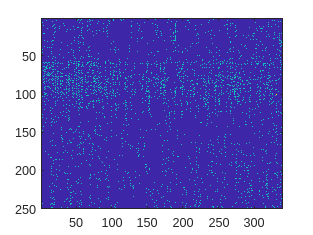

image(spike_counts_cell_3, 'CDataMapping','scaled')

 Remake the above plot but for cell number 30. What differences do you notice and why? 

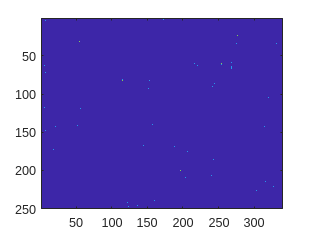

dd=spike_counts(:,:,30);
image(dd, 'CDataMapping','scaled')

What is the total spike count for the neurons recorded in the visual cortex?

mask = find(brain_areas=="visual cortex");
region_spike_counts = spike_counts(:,:,mask);
sum(region_spike_counts,"all")


Compute the mean spike counts across all cells in the visual cortex.  This essentially gives us the population activity for every trial across time. 

Visualise your result by plotting an image.

region_spike_counts = spike_counts(:,:,brain_areas=="visual cortex");
mean_spike_count = mean(region_spike_counts,3);

image(mean_spike_count, 'CDataMapping','scaled')
xlabel('trial')
ylabel('time bin')

If, in addition to the cells, we also take the average across time, we are left with a single value per trial representing the per-trial  population activity averaged over time. Compare the population activity  average over time between all neurons and visual cortex neurons. Is the visual cortex more active or less active compared to all areas together?

vis_cortex_data = spike_counts(:,:,brain_areas=="visual cortex");
visual_cortex_population_activity = mean(vis_cortex_data, [1,3]);
total_population_activity = mean(spike_counts, [1,3]);

clf
hold on
histogram(visual_cortex_population_activity, "DisplayName","Visual Cortex")
histogram(total_population_activity, "DisplayName","All Areas")
hold off

legend
xlabel('spike count')
ylabel('frequency')



The visual cortex has a different activity compared to all areas together, thus there must be other areas that are compensating for that. Which area is that?

region_population_activity = mean(spike_counts(:,:,brain_areas=="thalamus"), [1,3]);
total_population_activity = mean(spike_counts, [1,3]);
clf
hold on
histogram(region_population_activity, "DisplayName","Thalamus")
histogram(total_population_activity, "DisplayName","All Areas")
hold off

legend
xlabel('spike count')
ylabel('frequency')

## Spike Count Analysis with Trial-level Categorical Variables

As we have seen before, in addition to brain area, we also have access to several categorical variables such as response type and stimulus contrast level. Let's see whether the pattern of neural activity would change for different values of these categorical variables.

Let's start by turning the spike counts into firing rates.

dt = 0.01;
firing_rate = spike_counts/dt;

**Example:** Plot the mean firing rate (averaged across neurons and trials) over time, taking all neurons.

plot(mean(firing_rate, [2,3]))
xlabel('time bin')
ylabel('mean firing rate')

**Exercises**

From the file `steinmetz_2017-12-05_Lederberg.nc`, load in the `response_type` data and plot the mean firing rate only for trials where the response type is -1.

response_types = ncread("data/steinmetz_2017-12-05_Lederberg.nc","response_type") ;
firing_rate_response_neg_1 = firing_rate(:,response_types==-1,:);
plot(mean(firing_rate_response_neg_1,[2,3]))

xlabel('time bin')
ylabel('mean firing rate')


Add to the previous plot the other two response types: one line for each response type. Did the population activity of Visual Cortex change  noticable between the response types?

clf
hold on
plot(mean(firing_rate(:,response_types==-1,:),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,:),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,:),[2,3]), "DisplayName","+1")
hold off
xlabel('time bin')
ylabel('mean firing rate')
legend

Plot the same thing as in the previous exercise, but only for neurons in the Visual Cortex.

clf 
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas=="visual cortex"),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas=="visual cortex"),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas=="visual cortex"),[2,3]), "DisplayName","+1")
hold off
xlabel('time bin')
ylabel('mean firing rate')
legend

Using subplots, create four plots in a single figure, each plotting  showing the the analysis in the previous exercise for a different brain  area. Specify the brain area in the title.

Below is an example of how to use subplots.

clf
subplot(2,2,1)
region = "visual cortex";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,2)
region = "thalamus";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,3)
region = "hippocampus";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,4)
region = "non-visual cortex";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off